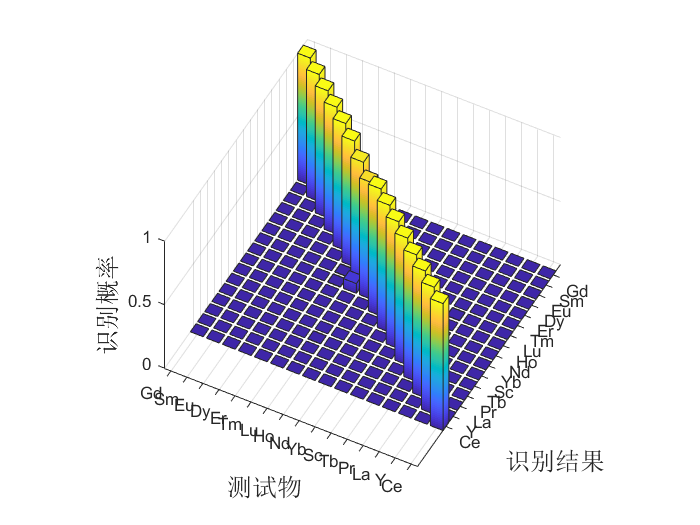

clear;close all;
load('nmlSpec.mat');
nSimSpec = 1000;
matMeasureTime = 600;
simMeasureTime = 10;
roi = zeros(size(mat,1),1);
roi(207:253) = 1; % 2223keV H-1
roi(473:516) = 1; % 4945keV C-12
roi(595:629) = 1; % 6111keV Cl-35
roi(746:803) = 1; % 7631&7646keV Fe-56
roi(1059:1109) = 1; % 10800keV N-14
roi = roi/sqrt(sum(roi.^2)); % 单位化


nRE = size(mat,2)-1;
resultTable = zeros(nRE,nRE);

for i = 1:nRE
    simSpec = zeros(size(mat,1),nSimSpec);
    for j = 1:size(simSpec,1)
        simSpec(j,:) = poissrnd(mat(j,i+1).*simMeasureTime./matMeasureTime,[1,nSimSpec]);
        %simSpec(j,:) = ones(1,nSimSpec)*mat(j,i);
    end % 产生模拟能谱
    [thisFoM,~] = sbrs_netv2([mat(:,1).*simMeasureTime./matMeasureTime,simSpec],mat.*simMeasureTime./matMeasureTime,roi);
    thisFoM = thisFoM(2:end,2:end); % 去除本底谱和本底谱的比较结果
    % 判别
    for j = 1:nSimSpec
        thisResult(1,j) = find(thisFoM(:,j)==min(thisFoM(:,j)));
    end
    for j = 1:nRE
        resultTable(i,j) = sum(thisResult==j)./nSimSpec;
    end
end

b = bar3(resultTable);
for k = 1:length(b)
    zdata = b(k).ZData;
    b(k).CData = zdata;
    b(k).FaceColor = 'interp';
end
xlabel('测试物','FontSize',15);
ylabel('识别结果','FontSize',15);
zlabel('识别概率','FontSize',15);
xticks(1:16);
xticklabels({'Gd','Sm','Eu','Dy','Er','Tm','Lu', ...
    'Ho','Nd','Yb','Sc','Tb','Pr','La','Y','Ce'});
yticks(1:16);
yticklabels({'Gd','Sm','Eu','Dy','Er','Tm','Lu', ...
    'Ho','Nd','Yb','Sc','Tb','Pr','La','Y','Ce'});

view([27.736 48.032])